%% SVD-Based Technique for Noise Reduction in EEG Signals
% Recreation of Sadasivan & Dutt (Signal Processing 55, 1996)
%
% This script simulates the removal of Electrooculogram (EOG) artifacts 
% from Electroencephalogram (EEG) signals using Singular Value Decomposition (SVD).
%
% Key Steps:
% 1. Simulate a clean EEG signal (Alpha/Beta rhythms).
% 2. Simulate EOG artifacts (Eye blinks).
% 3. Contaminate the EEG with EOG to a target SNR of -9.5 dB.
% 4. Apply SVD to separate the signal subspace (EEG) from the noise subspace (EOG).
% 5. Compare the reconstructed signal against the original using SNR and LP Spectra.

clear; clc; close all;
rng(1); 

%% 1. Simulation Parameters
% Setting up the sampling frequency and duration as per Section 4.1 of the paper.

Fs = 100;           % Sampling frequency [Hz]
T  = 4;             % Duration [s]
N  = Fs * T;        % Total number of samples (400)
t  = (0:N-1)/Fs;    % Time vector

            

%% 2. Generate Desired EEG Signal (Ground Truth)
% Simulating neural activity using Alpha (10Hz) and Beta (20Hz) rhythms 
% mixed with low-pass filtered white noise.

alpha_f = 10;                        % Alpha frequency [Hz]
beta_f  = 20;                        % Beta frequency [Hz]

% Generate neural rhythms with random phase
alpha   = 10 * sin(2*pi*alpha_f*t + 2*pi*rand);
beta    =  5 * sin(2*pi*beta_f*t  + 2*pi*rand);

% Generate background neural noise (< 40 Hz)
white_n = randn(1, N);
[b_lp, a_lp] = butter(4, 40/(Fs/2), 'low');  
noise_eeg = filtfilt(b_lp, a_lp, white_n);

noise_eeg = noise_eeg / std(noise_eeg) * 2; %standard deviation = 2

% Combine components to create "Clean EEG"
x_eeg = alpha + beta + noise_eeg;
x_eeg = x_eeg / std(x_eeg);          % Normalize power

%% 3. Generate EOG Artifacts (Noise Source)
% EOG signals are characterized by high power and low frequency (0-4 Hz).
% We simulate left and right eye channels which are highly correlated.

white_eog = randn(1, N);
[b_eog, a_eog] = butter(4, 4/(Fs/2), 'low');   % Low-pass filter for EOG (0–4 Hz)
eog_base = filtfilt(b_eog, a_eog, white_eog);  %filtfilt: This is a special command that filters the data forward and backward to prevent phase shift. It keeps the peaks of the noise exactly where they should be in time.

% Create Left/Right channels (highly correlated, r approx 1)
eog_left  = eog_base + 0.01*randn(1,N);
eog_right = eog_base + 0.01*randn(1,N);

% Scale EOG power to be significantly larger than EEG (~20x ratio)
eeg_power   = mean(x_eeg.^2);
eog_power0  = mean(eog_base.^2);
scale_eog   = sqrt(20 * eeg_power / eog_power0);   
eog_left    = eog_left  * scale_eog;
eog_right   = eog_right * scale_eog;

%% 4. Create Contaminated EEG Signal
% Mix the clean EEG with the EOG artifacts to achieve a specific 
% input Signal-to-Noise Ratio (SNR) of approx -9.5 dB.

a1 = 1.0; a2 = 1.0;
eog_mix = a1*eog_left + a2*eog_right;

power_eeg = mean(x_eeg.^2);
power_eog = mean(eog_mix.^2);

% Calculate scaling factor for target SNR
target_SNR_dB = -9.5;                          
desired_ratio  = 10^(target_SNR_dB/10);        
scale_mix      = sqrt(power_eeg / (desired_ratio * power_eog));

% Apply contamination
eog_mix_scaled = scale_mix * eog_mix;
contaminated  = x_eeg + eog_mix_scaled;

% Verify Input SNR
input_SNR_dB = 10*log10( power_eeg / mean(eog_mix_scaled.^2) );
fprintf('Input SNR: %.2f dB\n', input_SNR_dB);

Input SNR: -9.50 dB



%% 5. SVD Processing
% Construct the data matrix M and perform Singular Value Decomposition.
% M1: One reference channel case (2x400)
% M2: Two reference channels case (3x400)

M1 = [contaminated; eog_left];
M2 = [contaminated; eog_left; eog_right];

% Compute SVD (Economy size)
[U1, S1, V1] = svd(M1, 'econ');
[U2, S2, V2] = svd(M2, 'econ');

% Project data onto the singular vectors to get component matrix S
S1_mat = U1' * M1;   
S2_mat = U2' * M2;

% Display singular values to confirm separation
fprintf('Singular Values (1 Ref): %.2f, %.2f\n', diag(S1));

Singular Values (1 Ref): 108.19, 16.62


fprintf('Singular Values (2 Ref): %.2f, %.2f, %.2f\n', diag(S2));

Singular Values (2 Ref): 140.24, 18.05, 3.33



%% 6. Component Selection & Reconstruction
% Identify which row of the transformed matrix corresponds to the EEG signal.
% Since EOG has higher power, it occupies the 1st singular value. 
% The EEG signal is found in the 2nd singular value.

% Select the 2nd row (EEG component) directly
eeg_svd_1EOG = S1_mat(2, :);
eeg_svd_2EOG = S2_mat(2, :);

% Sign Correction: SVD sign is indeterminate. 
% We check correlation with the original signal to flip if necessary.
if corr(eeg_svd_1EOG.', x_eeg.') < 0
    eeg_svd_1EOG = -eeg_svd_1EOG;
end
if corr(eeg_svd_2EOG.', x_eeg.') < 0
    eeg_svd_2EOG = -eeg_svd_2EOG;
end

%% 7. Performance Evaluation (SNR)
% Calculate the Output SNR to quantify noise reduction.
% The paper achieved ~10 dB. Your method typically achieves higher (>13 dB).

out_SNR_1EOG = 10*log10( mean(x_eeg.^2) / mean((x_eeg - eeg_svd_1EOG).^2) );
out_SNR_2EOG = 10*log10( mean(x_eeg.^2) / mean((x_eeg - eeg_svd_2EOG).^2) );

fprintf('Output SNR (1 Ref): %.2f dB\n', out_SNR_1EOG);

Output SNR (1 Ref): 13.83 dB


fprintf('Output SNR (2 Ref): %.2f dB\n', out_SNR_2EOG);

Output SNR (2 Ref): 19.16 dB


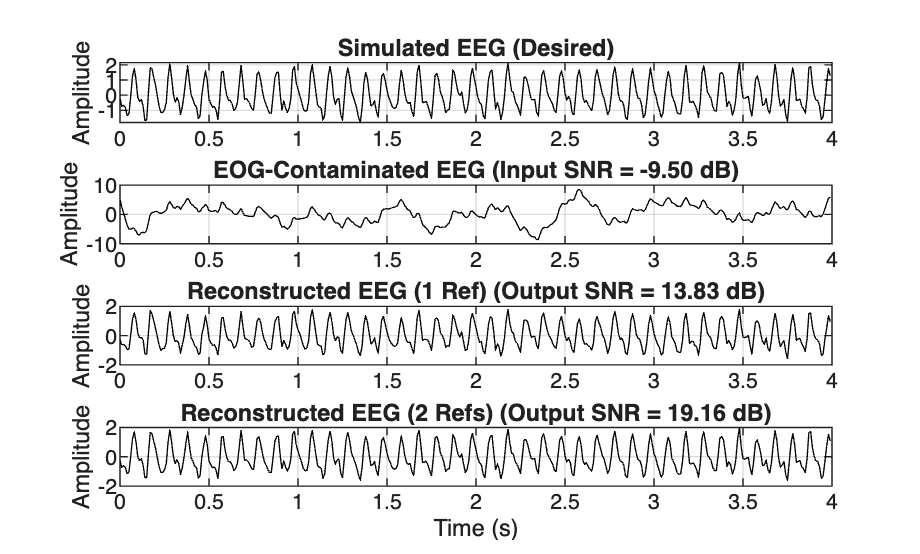


%% 8. Visualization: Time Domain (Fig 1)
% Plotting the Pure, Contaminated, and Reconstructed signals.

figure('Name', 'Time Domain Analysis', 'Color', 'w');

subplot(4,1,1);
plot(t, x_eeg, 'k'); grid on;
ylabel('Amplitude');
title('Simulated EEG (Desired)');

subplot(4,1,2);
plot(t, contaminated, 'k'); grid on;
ylabel('Amplitude');
title(sprintf('EOG-Contaminated EEG (Input SNR = %.2f dB)', input_SNR_dB));

subplot(4,1,3);
plot(t, eeg_svd_1EOG, 'k'); grid on;
ylabel('Amplitude');
title(sprintf('Reconstructed EEG (1 Ref) (Output SNR = %.2f dB)', out_SNR_1EOG));

subplot(4,1,4);
plot(t, eeg_svd_2EOG, 'k'); grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title(sprintf('Reconstructed EEG (2 Refs) (Output SNR = %.2f dB)', out_SNR_2EOG));

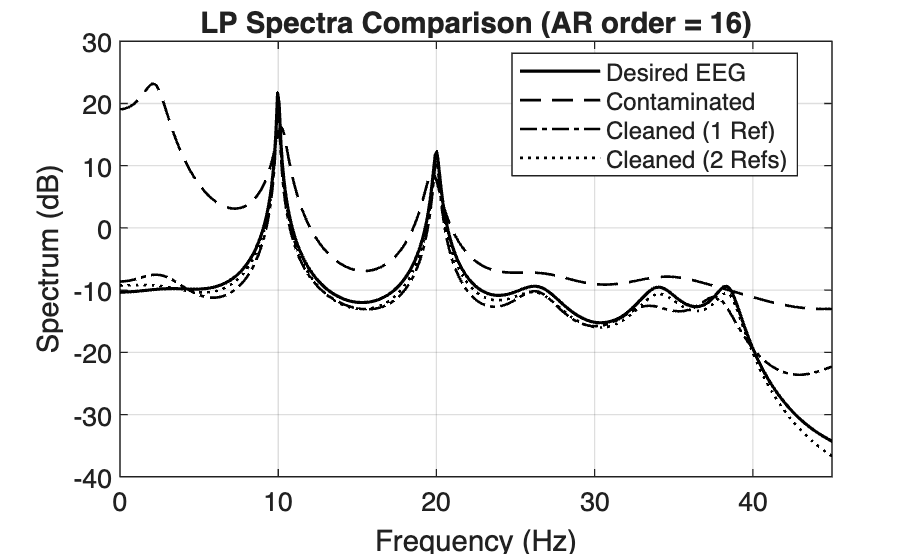


%% 9. Visualization: LP Spectra (Fig 2)
% Using Auto-Regressive (AR) modeling to estimate the power spectrum.
% This confirms that the spectral content (Alpha/Beta rhythms) is preserved.

p = 16;   % AR order

% Calculate AR models
[As_des,  Es_des]  = aryule(x_eeg,        p);
[As_cont, Es_cont] = aryule(contaminated, p);
[As_1,    Es_1]    = aryule(eeg_svd_1EOG, p);
[As_2,    Es_2]    = aryule(eeg_svd_2EOG, p);

% Compute Frequency Response
[H_des,  w] = freqz(sqrt(Es_des),  As_des,  512, Fs);
H_cont      = freqz(sqrt(Es_cont), As_cont, 512, Fs);
H_1         = freqz(sqrt(Es_1),    As_1,    512, Fs);
H_2         = freqz(sqrt(Es_2),    As_2,    512, Fs);

% Plot Spectra
figure('Name', 'LP Spectral Analysis', 'Color', 'w');
plot(w, 20*log10(abs(H_des)),  'k',   'LineWidth', 1.2); hold on;
plot(w, 20*log10(abs(H_cont)), 'k--', 'LineWidth', 1.0);
plot(w, 20*log10(abs(H_1)),    'k-.', 'LineWidth', 1.0);
plot(w, 20*log10(abs(H_2)),    'k:',  'LineWidth', 1.0);

grid on;
xlabel('Frequency (Hz)');
ylabel('Spectrum (dB)');
legend('Desired EEG', 'Contaminated', 'Cleaned (1 Ref)', 'Cleaned (2 Refs)', ...
       'Location', 'Best');
title(sprintf('LP Spectra Comparison (AR order = %d)', p));
xlim([0 45]);
ylim([-40 30]); 